# Using population decoding to analyze neural data

A central goal of Neuroscience research is to understand how neural activity enables animals to perform complex behaviors. To study this, neuroscientists make different types of neural recordings, including functional magnetic resonance imaging (fMRI) and electroencephalography (EEG) recordings from humans, and recording action potential of individual neurons. Once this data is recorded, neuroscientists then need to apply a data analyses to turn the recorded signals into information that can lead to an understanding of how the brain is processing information. 

One method that has been shown to be very useful for interpreting neural activity is called *neural population decoding* (the method is also referred to as *multi-voxel pattern analysis* by the fMRI community). The purpose of this tutorial is to explain what neural decoding is and how to run a decoding analysis in MATLAB. 

## An example experiment

To illustrate how neural decoding works, we will use data from an experiment run by Ying Zhang and Bob Desmione at MIT [1], which will will refer to as the Zhang-Desimone experiment. On each trial in this experiment, a monkey fixed on a dot for 500 ms, and then one of seven possible images was shown to the monkey for 500 ms (figure 1).  While the monkeys viewed these images, Ying recorded the spiking activity from 132 neurons in the inferior temporal cortex (IT) which is a brain region thought to be involved with objet recognition. Each experimental trial type was repeated ~60 times to collect a data set that had spiking activity from 420 trials (7 trials * 60 repeitions = 420 trials total). (The actual experiment was a bit more complex and consisted of showing the images at different locations and also an attentional manipulation but we will ignore this for now). 

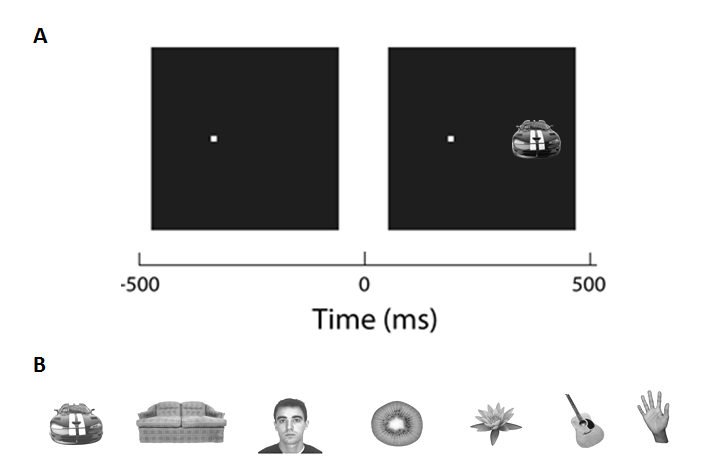

***Figure 1.****  An example experiment run by Ying Zhang and Bob Desimone at MIT. ****A****, An example of an experimental trial where the monkey fixated for 500 ms and then was showng a stimulus for 500 ms. ****B****, the seven diffrent stimuli that could be shown to the monkey. Each stimulus was shown 60 times (20 times at each location) while the spiking activity of 132 neurons was recorded. *

## What is neural population decoding?

Neural population decoding is a data analysis method where a computer program, called a *pattern classifier*, uses neural activity to predict what experimental conditions are present on a particular experimental trial. The the pattern classifier can predict what experimental conditions are present based on neural activity at a level that is above chance, this means that there is a reliable relationship between the neural activity an different experimental conditions, or put another way, there is information about the experimental conditions in the neural activity. 

Figure 2 illustrates how this process works on one trial from the Zhang-Desimone experiment. On the trial shown in figure 2, a monkey was shown an image of a kiwi (Fig. 2A) while 132 neurons were recorded (Fig. 2B). The activity of these neurons was then fed into a pattern classifier (Fig. 2C) and the classifier predicted that a kiwi was present on this trial (Fig 2D). Since in a kiwi was in fact shown on this trial, the prediction made by the classifier is marked as being corrected (Fig. 2E). This process is then repeated for many different trials, and the percentage of correct predictions is reported. If the pattern classifer was merely guessing which image was shown on each trial, then we would expect correct predictions to be made on approximate 1 out of every 7 trials, since there are 7 different possible images the classifier has to choose between. If the prediction accuracy is well above 1/7, then the classifier is unlikely to be guessing, which means there is a reliable relationship between the stimuli and the neural activity. 

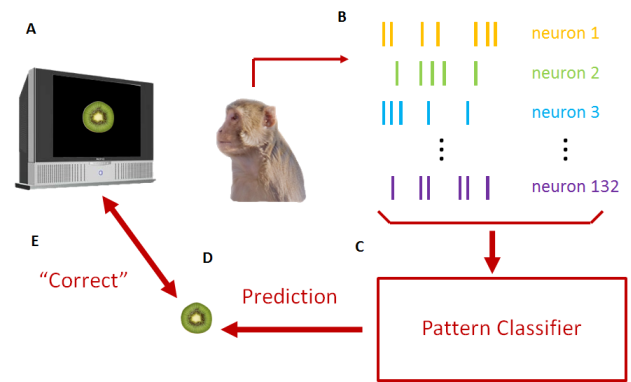

***Figure 2.****  An example showing a decoding analysis for one trial form the Zhang-Desimone experiment. ****A****, On this trial, the monkey is shown an image of a kiwi. ****B****, While the monkey views the image, the spiking activity of 132 neurons is recorded. ****C****, This neural activity is fed into a pattern classifier.**** D****, The pattern classifier then makes a prediction about what image it thinks is present based on the neural activity. In this example, the classifier predicted the image was of a kiwi.  ****E****, The prediction of the classifier is then compared to the image that was actually shown to the monkey. In this example, the classifiers prediction was correct, so we make it a correct prediction. This process (steps A to E) is repeated over many trials, and the average prediction accuracy is reported as the final statistic from this analysis. If the average prediciton accuracy is well above chance, then it means there is a reliable relationship between the neural activity and the different images, or in other words, the neural activity has information about the stimuli [2].*

## Training the classifier to make predictions

In order for the pattern classifier to be able to make correct predictions, the classifier must be able to *learn* the relationship between between different patterns of neural activity and different experimental conditions.  To do this, the neuron recordings from different trials are divided into two non-overlapping sets of data. One set of data is called the *training set *and is used by the pattern classifier to learn the relationship between the neural recordings and experimental conditions. The second set of data is called the *test set*, and the classifier must take this test set and try to correct predict which experimental conditions were present on all of the trials in this set. Again, if the classifier can make correct predictions on the test set, it means there is a reliable relationship between the neural activity and the different experimental conditions. In a typical decoding analysis, a '*cross-validation*' process is used where the process of dividing the data into different training and test sets is repeated many times, and the final decoding accuracy is averaged over many different training and test splits. For more information about how decoding works, see reference [3]. 

## Downloading and setting up the Neural Decoding Toolbox (NDT) 

In order to illustrate how to run a decoding analyses on the Zhang-Desimone data, we will use MATLAB and the Neural Decoding Toolbox (NDT) [4]. You can download the NDT and set the toolbox path using the following steps:

- Register to download the toolbox by going to  [http://www.readout.info/wp-login.php?action=register](http://www.readout.info/wp-login.php?action=register) and filling out the form. Once you fill out the form you will receive an email with a link you can click on to finish confirming your registration. 

- After have an account, you should log into the [http://www.readout.info](http://www.readout.info ) website. You can then download the toolbox from [http://www.readout.info/downloads/download-the-toolbox/](http://www.readout.info/downloads/download-the-toolbox/)  and clicking on the 'Downlad the latest version of the Neural Decoding Toolbox' link. 

- You should download the data from Zhang-Desiomone experiment from [http://www.readout.info/downloads/datasets/zhang-desimone-7-object-dataset/](http://www.readout.info/downloads/datasets/zhang-desimone-7-object-dataset/) by clicking on the 'Download the Zhang-Desimone 7 object dataset' link. 

- After the NDT and the Zhang-Desimone .zip files have been downloaded, unzip them and place the two folders in a directory where you would like to do your analyses; e.g., you should have a directory that contaings the folders with names ndt.1.0.4/ and Zhang_Desimone_7objects_raster_data/. Then open MATLAB, and set your MATLAB current folder to be the folder that contains these directories. 

- Finally, run the following command to set the MATLAB path to contain the NDT:

% add the path to the NDT so add_ndt_paths_and_init_rand_generator can be called
toolbox_basedir_name = 'ndt.1.0.4/';
addpath(toolbox_basedir_name);
 
% add the NDT paths using add_ndt_paths_and_init_rand_generator
add_ndt_paths_and_init_rand_generator

toolbox_basedir_name = C:\Users\CSEMeyers\Documents\GitHub\NDT_tutorial\ndt.1.0.4/

initializing the matlab random number generator to an aribrary clock value, i.e., the 'rand' function should now work properly


If everything has worked correctly you should see a message that says: *'initializing the matlab random number generator to an aribrary clock value, i.e., the 'rand' function should now work properly'*

## Binned the Zhang-Desimone data

When we described the decoding process above, we said that the pattern classifier was trained and tested using neural spiking data. However, usually when we do a decoding analysis on neural spiking data we don't pass the classifer the exact spike times, but instead we pass the classifier a list of the number of spikes that occurred in a given time window on each trial  - i.e., we pass the classifier the *spike count firing rate* rather than the exact spike times. The Zhang-Desimone data you downloaded  contains exact spike times, so for the first step in our data analysis we need to *'bin the data'* by converting the spike times into a spike count firing rate. 

Rather than converting all the spike times into a single firing rate on each trial, we typically bin the data from a trial into a number of sub-bins. For example, each experimental trial in Zhang-Desimone data is 1 second long (i.e., 500 ms of fixation and 500 ms of stimulus presentation), and rather than binned the data into a single 1 second bin that counts all the spikes that occured on a trial, we can instead bin the data into a sequence of 100 ms bins that span the full 1 second trial length; if the bins do not overlap, we would have 10 bins of 100 ms length that will span the 1 second trial. The coding analysis will then be run separately on each spike counts in each bin to get an estimate of how the information varies as a funciton of time; for the Zhang-Desimone data, we should not expect to be able to decode what stimulus is present during the fixation period prior to the stimulus onset (since the monkey is not psychic) but if there is information in the neural activity, we should be able to decode the stimulus sometime after it has been presented. 

Finally, we can also have the bins overlap to get a smoother estimate of the information as a function of time.  To do this we need to specify the *sampling interval *which says how often we should create bins. For example, if we use bins that are 100 ms in length, and a sampling interval of 50 ms, then each adjacent bin will have a 50% overlap, and there will be 21 spike count bins with rnages of 1-100 ms, 51-150 ms, 101-150 ms, etc.  Figure 3 illustrates this binning process. 

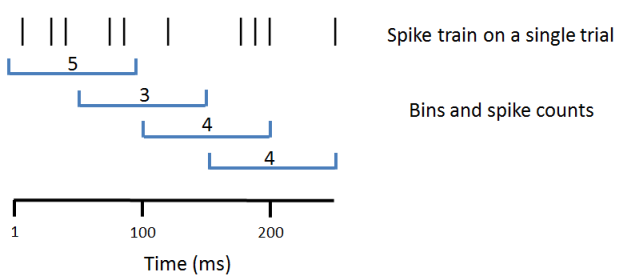

***Figure 3.**** Illustration of how spike trains are binned into spike count firing rates. The upper sequence of vertical bars represents the times of spikes in the first 250 ms of a spike train from a single trial.  The blue brackets represent four 100 ms bins, and the numbers in the brackets represent the spike counts in each bin. The bins are sampled every 50 ms and thus they overlap. The output of the binning process is a sequence of spike counts that start with 5, 3, 4, 4, etc. This binning process will be done for every trial and for all neurons, and this binned test data will be passed the a pattern classifier to make predictions about what happened on each trial. *

To bin the data using the NDT, we can use the function *create_binned_data_from_raster_data *as follows: 

% The name of the directory that has the spike data files
spike_file_directory_name = 'Zhang_Desimone_7objects_raster_data/';

% A name to use when the results as saved
save_prefix_name = 'Binned_ZD_data';

bin_size = 100;
sampling_interval = 50;
 
create_binned_data_from_raster_data(spike_file_directory_name, save_prefix_name, bin_size, sampling_interval);


 Binning the data: 1 of 132
��������������������������� Binning the data: 2 of 132��������������������������� Binning the data: 3 of 132��������������������������� Binning the data: 4 of 132��������������������������� Binning the data: 5 of 132��������������������������� Binning the data: 6 of 132��������������������������� Binning the data: 7 of 132��������������������������� Binning the data: 8 of 132��������������������������� Binning the data: 9 of 132��������������������������� Binning the data: 10 of 132���������������������������� Binning the data: 11 of 132���������������������������� Binning the data: 12 of 132���������������������������� Binning the data: 13 of 132���������������������������� Binning the data: 14 of 132���������������������������� Binning the data: 15 of 132���������������������������� Binning the data: 16 of 132���������������������������� Binning the data: 17 of 132���������������������������� Binning the data: 18 of 132���������������������������� Binning

If the function works correctly it should create an output file called *Binned_ZD_data_100ms_bins_50ms_sampled.mat *which contains the binned data. We will use this file in subsequent decoding analyses. 

## Running a decoding analysis using the NDT

Now that the data has been binned into spike count firing rates, we can begin to run a decoding analyses. To run a decoding analyses using the NDT requires specifyiing 4 different MATLAB objects which are: 

- A **datasource** that will return training and test splits of the data. We will use the NDT's *basic_DS* datasource, and we will pass it the binned Zhang-Desimone data we created above. Additionally, we will specify that we will use 20 cross-validation splits, which means that the classifier will be trained and tested 20 times at each time bin (and this whole process will be repeated multiple times to get a smooth estimate of the prediction accuracy). Finally, we need to specify that we want to decode which image was shown on a given trial by using the 

- A **classifier **that will be used be used to predict which image was shown on each trials. We will use a *maximum correlation coefficent* (MCC) classifier, which in the NDT is called *max_correlation_coefficient_CL*.  In general we have found the results do not vary much depening on which classifier we use, which is a good thing since it shows that the analysis is robust and depends mostly on the data.

- A **feature preprocessor** that will be used to do some pre-processing of the data. We will use the NDT's* zscore_normalize_FP* feature-preprocessor which normalizes each neurons' spike count activity to have a mean of 0 and a standard deviation of 1. This is useful because different neurons often fire at very different firing rates (e.g., neurons only spike around 5 Hz, while others can spike at rates over 100 Hz), although in general the results are pretty robust to this normalization. 

- A **cross-validator** that will run multiple cross-validation cycles, where in each cycle:   a) the datasource is used to get training and test data, b) the feature-processor processes the data, c) the classifier is trained using the training data, and the prediction accuracy is assessed on the test data, and d) the cross-validation cycle is repeated multiple turns. The results are then saved so that they can be plotted. 

The code below shows how this is done in MATLAB using the NDT:


% Create a datasource that takes our binned data, and specifies that we want to decode
%  the stimulusID of which image was shown on each trial, and that we want to do 
%  20 cross-validation runs
ds = basic_DS('Binned_ZD_data_100ms_bins_50ms_sampled.mat', 'stimulus_ID', 20);
 
% Create a MCC classifier
the_classifier = max_correlation_coefficient_CL;

% Create a feature preprocessor that z-score normalizes each neuron
the_feature_preprocessors{1} = zscore_normalize_FP;
 
% Create the cross-validator that takes the datasource classifier and feature processor
the_cross_validator = standard_resample_CV(ds, the_classifier, the_feature_preprocessors);
 
% To speed up the computations in this tutorial we will also only run 2 decoding cycles
% although one can get more accurate results by running more cycles (the default is 50 cycles) 
the_cross_validator.num_resample_runs = 2;
 

Once we have created these objects we can use cross-validator's run_cv_decoding method to run the decoding analysis, and we will save the results as follows: 

% Run the decoding analysis
DECODING_RESULTS = the_cross_validator.run_cv_decoding;

Starting decoding analysis
initializing basic_DS.get_data

Completed 1 of 2 resample runs.  The last run took 14 seconds.

  Columns 1 through 14

   13.5714   21.4286   18.5714   15.7143   10.0000   12.1429   12.8571   15.0000   15.0000   16.4286   20.0000   60.7143   87.1429   86.4286
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

  Columns 15 through 19

   82.8571   79.2857   67.8571   73.5714   62.1429
       NaN       NaN       NaN       NaN       NaN



Completed 2 of 2 resample runs.  The last run took 7 seconds.

  Columns 1 through 14

   15.7143   19.2857   16.4286   11.7857   12.5000   12.8571   15.3571   22.1429   18.5714   16.4286   21.4286   59.6429   83.9286   82.1429
    3.0305    3.0305    3.0305    5.5558    3.5355    1.0102    3.5355   10.1015    5.0508         0    2.0203    1.5152    4.5457    6.0609
       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

 
% Save the results to a file called ZD_results.mat
save('ZD_results.mat', 'DECODING_RESULTS');

## Plotting the results

Now that we have run the decoding analyses, it is time to plot the results to see if we can predict which image is shown on each trial at a level that seems to be above chance. We can use NDT's *plot_standard_results_object* to plot the results, and all we need to pass this function is a cell array with the results we want to plot (since we are only plotting a single decoding result, the cell array only has one entry). Below is the code that plots the results:

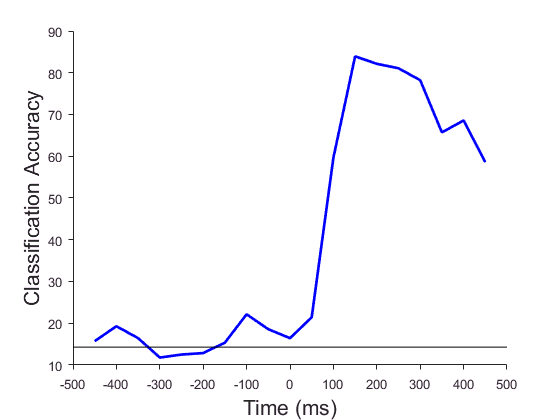

% Specify the name of the file that we want to plot
result_names{1} = 'ZD_results.mat';  
 
% Create a plot_standard_results_object to plot the results
plot_obj = plot_standard_results_object(result_names);
 
% Call the plot_results method to display the results
plot_obj.plot_results;

The plot of the result show that during the baseline period the prediction accuracy is around chance (1/7 = 14%, black vertical line). However, shorting after the onset of the stimulus (time 0) the decoding accuracy rises rapidly and reaches a peak accuracy of around 80% correct before dorpping off a bit. Thus, there does indeed appear to be information to discriminate between visual objects in the spiking activity of neurons in the interior temporal cortex.

## Conclusions

The tutorial above shows you how to apply basic decoding analyses to neural data, however it only scratches the surface of what is possible to do using decoding analyses. The exercises allow you to explore basis analyses in more depth and try more advanced decoding analyses that can give deeper insight into neuron content and coding, and the references at the end of the paper also show examples of deeper insights that can be extracted using neural population decoding. 

## Additional exercises

**Exercise 1:** In the above tutorial we mention that the decoding analyses are fairly robust to changes in the decoding parameters. However, you shouldn't take our word for it, but rather you should verify this for yourself! To do this, try out different decoding parameters, save the results under different names, and the plot the results to compare them. For example, we can compare how good the results are when we do not use the z-score normalization feature-preprocessor using the following code: 

% Do not use a feature-preprocessor
the_feature_preprocessors = [];
 
% Create the cross-validator that takes the datasource classifier and the empty feature-processor
the_cross_validator = standard_resample_CV(ds, the_classifier, the_feature_preprocessors);
the_cross_validator.num_resample_runs = 2;

% Run the decoding analysis without the preprocessor
DECODING_RESULTS = the_cross_validator.run_cv_decoding;

Starting decoding analysis

Completed 1 of 2 resample runs.  The last run took 7 seconds.

  Columns 1 through 14

    9.2857   14.2857    9.2857   12.1429    9.2857   12.8571    9.2857   13.5714   15.0000   10.0000    6.4286   39.2857   72.8571   70.7143
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

  Columns 15 through 19

   67.8571   61.4286   57.8571   45.7143   44.2857
       NaN       NaN       NaN       NaN       NaN



Completed 2 of 2 resample runs.  The last run took 7 seconds.

  Columns 1 through 14

   12.8571   14.6429   10.3571   13.2143   12.5000   10.7143   11.7857   14.6429   16.7857   11.0714    8.2143   42.1429   75.0000   72.8571
    5.0508    0.5051    1.5152    1.5152    4.5457    3.0305    3.5355    1.5152    2.5254    1.5152    2.5254    4.0406    3.0305    3.0305
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   

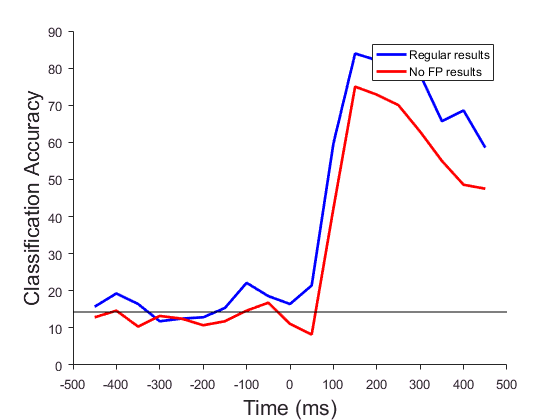


% Save the results to a file called ZD_results_no_FP.mat
save('ZD_results_no_FP.mat', 'DECODING_RESULTS');

% Plot the results to compare them to the origional results
result_names{2} = 'ZD_results_no_FP.mat';  
plot_obj = plot_standard_results_object(result_names);
plot_obj.legend_names = {'Regular results', 'No FP results'};
plot_obj.plot_results;

Other parameters to test out are using differeent binning schemes (bin sizes and sampling intervals), and using some of the different feature-preprocessors and/or classifiers listed in the documentation on [http://www.readout.info](http://www.readout.info) 

**Exercise 2:** Although we didn't mention this in the above tutorial, the 7 objects shown in the Zhang-Desimone study were actually shown at 3 different positions on the screen: an upper position, a middle position, and a lower position (the image is shown in the middle position in figure 1). Thus the ~60 repetitions of the 7 images were really divided to ~20 repetitions of each image shown at each of these 3 locations. When we did the decoding analysis in the tutorial we ignored the position of where the image was shown, and only tried to decoding the objects' indentity, which we specified when we created the datasouce by using the arguement  'stimulus_ID' when we created the basic_DS. However, we could do an analysis where we set alternatively try to decode the position of the image, ignore which image was shown. Try  running this decoding analysis by creating a basic datasource that using the image's position instead of the images identity using the code: 

% Create a datasource to decode the stimulus position
ds = basic_DS('Binned_ZD_data_100ms_bins_50ms_sampled.mat', 'stimulus_position', 20);

% You can use the same code for the results of the analyses, although save the results with a different name:
the_classifier = max_correlation_coefficient_CL;
the_feature_preprocessors{1} = zscore_normalize_FP;
the_cross_validator = standard_resample_CV(ds, the_classifier, the_feature_preprocessors);
the_cross_validator.num_resample_runs = 2;
DECODING_RESULTS = the_cross_validator.run_cv_decoding;

Starting decoding analysis
initializing basic_DS.get_data

Completed 1 of 2 resample runs.  The last run took 5 seconds.

  Columns 1 through 14

   35.0000   38.3333   33.3333   38.3333   36.6667   30.0000   40.0000   38.3333   21.6667   36.6667   31.6667   38.3333   31.6667   46.6667
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

  Columns 15 through 19

   56.6667   53.3333   61.6667   56.6667   43.3333
       NaN       NaN       NaN       NaN       NaN



Completed 2 of 2 resample runs.  The last run took 5 seconds.

  Columns 1 through 14

   34.1667   35.0000   30.8333   39.1667   33.3333   33.3333   37.5000   38.3333   23.3333   31.6667   25.8333   45.8333   37.5000   50.8333
    1.1785    4.7140    3.5355    1.1785    4.7140    4.7140    3.5355    0.0000    2.3570    7.0711    8.2496   10.6066    8.2496    5.8926
       NaN       NaN       NaN       NaN       NaN       NaN       NaN  

save('ZD_position_results.mat', 'DECODING_RESULTS');

% plot the results here...

Plot the results to see whether it possible to decoding the position of the image from inferior temporal cortex neurons (and what is chance decoding here)? 

**Exercise 3: **Another well-known property of neurons in the inferior temporal cortex (ITC) is that their responses are fairly position invariant, meaning that if a neuron has a higher firing rate to image A than to image B at one location on the screen, the neuron will also usually have a higher firing rate to image A compared to image B at all other locations on the screen. To test whether this is the case using decoding, what we can do is train a classifier to discriminate between the 7 objects at one location on the screen (say the upper location) and then have the classifier make predictions based on trials where the images were shown at a different location (say the lower location). If the classifier can generalize across different training and testing locations, this means that the representations in the ITC are position invariant. 

The NDT has a datasouce, called the generalization_DS that makes it easy to train the classifier on one set of conditions and test the classifier on a different set of conditions. There is also a tutorial at [http://www.readout.info/tutorials/generalization-analysis/](http://www.readout.info/tutorials/generalization-analysis/) that describes in more detial how to do this type of 'generalization analysis'. For this exercise, try to run thought this generalization tutorial to see if the ITC is position invariant. This type of generalization analysis is pretty powerful and has been used to show that there are populations of neurons that are selective for images of individual people regardless of head angle of the person [5] and that training on a task changes the representations in ITC and the prefrontal cortex [6].

**Exercise 4: **The results we plotted in the tutorial (and in all the other exercises) are based on training and testing the classifier using data from recorded in the same time bin, and then moving on and repeating the process for the next time bin, etc. However, one can imagine training the classifier at one point in time and then testing the classifier with data from a different point in time to see if the classifier can generalize across time. If the classifier can generalize across time, then it means that information is coded the same way across time (i.e., there is a *static code*), while if the classifier cannot generalize across time, it means that different patterns of neural activity code information at different time points in the experiments (i.e, there is a *dynamic code*). 

Training the classifier with data from one time bin, and testing the classifier using data from a different time bin is called a *temporal cross-generalization* (or temporal cross-training) analysis. Several studies have done temporal cross-decoding analyses, with some studies showing a dynamic code (e.g., [6]) and other studies showing a static code (e.g, [1]). Understanding why the brain to use a static vs. a dynamic code is still currently an open question.  

The NDT by default runs a temporal cross-training and in fact you have already run temporal generalization analyses when you created the results in the tutorial. However in order to plot the temporal generalization-decoding results, you need to use the *plot_standard_results_TCT_object *as follows: 

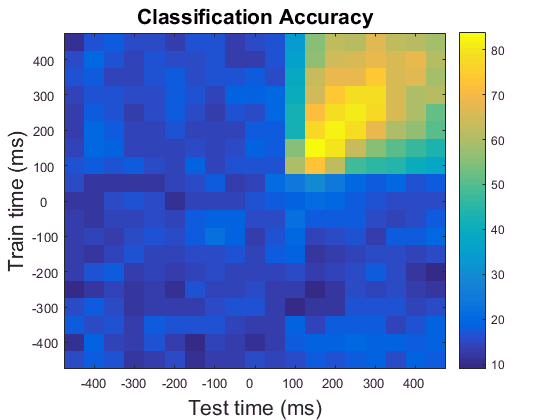

% Create plot_standard_results_TCT_object to plot the temporal cross-decoding results
plot_obj = plot_standard_results_TCT_object('ZD_results');
 
% By default the NDT plays a movie of the results, which we will turn off here.
plot_obj.display_TCT_movie = 0;

% Plot the results 
plot_obj.plot_results;

The results from the temporal cross-generalization analysis show a matrix where the classifier is trained at one time bin (indicated by the y-axis) and tested at either the same time bin (the diagonal elements of the matrix) or tested at a different time bin (the off diagonal elements of the matrix). The diagonal of the matrix are the same results plotted in the tutorial. As can be seen, the results show a fairly square region of good decoding performance, indicating a mostly static code in this data. 

For this exercise, plot the temporal cross-decoding matrix for the position decoding results that were created in exercise 2 and describe whether these results also appear static or wehther they are dynamic (for more examples to compare to see references, [6], [7] and [8]). 

**Exercise 5:** All the analyses that have been done so far have been on the Zhang-Desimone dataset. There are currently two other datasets that can be downloaded from the [http://www.readout.info](http://www.readout.info) website which you can try decoding analyses on. This first dataset was made by Sue-Lian Qi and Chirstos Constantinidis at Wake Forest and consists of data that was recorded from the prefrontal cortex before and after monkeys were trained to perform a delayed match-to-sample task. The data can be downloaded using at [http://www.readout.info/downloads/datasets/qi-constantinidis-pre-and-post-training-dataset/](http://www.readout.info/downloads/datasets/qi-constantinidis-pre-and-post-training-dataset/) and more information about decoding analyses using this data can be found at [8]. Using this dataset, see if you can decoding whether a given trial was a match or a non-match trial, and also whether there is visual information in the prefrontal cortex. 

The second data set consists of magnetoencephalography (MEG) recordings made by Leyla Isik who was examining object selectivity and invariance in human participants; the data can be downloaded from [http://www.readout.info/downloads/datasets/isik-26-letter-meg-dataset/](http://www.readout.info/downloads/datasets/isik-26-letter-meg-dataset/) although it should be noted that his dataset is very large (2.5GB). Using this data, see if you can decoding whether there is visual information in the MEG recordings and whether the information is contained in a position invariant code (i.e., follow the analyses in exercise 3 to test for position invariance). 

## References 

[1] Zhang Y, Meyers E, Bichot N, Serre T, Poggio T, and Desimone R (2011). Object decoding with attention in inferior temporal cortex. *Proceedings of the National Academy of Sciences*, 108:8850-8855.

[2] Quian Qurioga R, and Panzerri S (2009). Extracting information from neuronal populations: information theory and decoding approaches. *Nature Reviews Neuroscience*, 10(3):173-85.

[3] Meyers E, and Kreiman G (2011). Tutorial on Pattern Classification in Cell Recording. In: Visual population codes. Kreigeskorte, N., and Kreiman, G. (eds.), MIT Press.

[4] Meyers E (2013). The Neural Decoding Toolbox. *Frontiers in Neuroinformatics*, 7:8.

[5] Meyers E, Borzello M, Freiwald W, Tsao D (2015). Intelligent Information Loss: The Coding of Facial Identity, Head Pose, and Non-Face Information in the Macaque Face Patch System. *Journal of Neuroscience*, 35(18):7069-81.

[6] Meyers, E., Freedman, D., Kreiman, G., Miller, E., Poggio T. (2008). Dynamic Population Coding of Category Information in Inferior Temporal and Prefrontal Cortex. *Journal of Neurophysiology*, 100:1407-1419.

[7] Isik, L., Meyers, E., Leibo, J., Poggio, T. (2014). The dynamics of invariant object recognition in the human visual system. *Journal of Neurophysiology*, 111:91102.

[8] Meyers, E., Qi, X.L., Constantinidis C. (2012). Incorporation of new information into prefrontal cortical activity after learning working memory tasks. *Proceedings of the National Academy of Sciences*, 109:4651-4656.

[9] Additional publications that use the NDT can be found at:  [http://www.readout.info/about/publications/](http://www.readout.info/about/publications/) 